*madeToMeasure* accompanies the *Photon-efficient optical tweezers via wavefront shaping* paper and optimises optical traps for spherical particles.

There are some different options for choosing the features of the optimised trap. These are set by the string variable "optimCase", which lists the objective function and the constraints. Currently the only supported objective function ('obj:') is x-stiffness ('Kx'). A number of different constraints ('st:') can be specified, e.g. 'Ky=Kx' means that we want y-stiffness to be the same as x-stiffness, 'Fz=0' means that the z-force is to be zero (at the origin), etc. The two options for "optimCase" specified in this code are the ones we used in the paper:

- 'obj:Kx_st:Kz=Kx*R,Fz=0,Kx<=0' (for cases where field symmetry is enforced, e.g. with L_max = 0, polrz = [1 1i])

- 'obj:Kx_st:Ky=Kx,Kxy=Kx,Kxny=Kx,Kz=Kx*R,Fx=0,Fy=0,Fz=0,Kx<=0' (for cases where field symmetry is not enforced)

The constraints are fairly customisable, but note that the reported stiffness enhancement and volume reduction values are correct only if the optimised trap has an equilibrium at the origin, i.e. if the Fz=0 constraint was used. Otherwise, it is more than likely that the optimised trap is unstable in z. Strictly speaking, the Fx=0,Fy=0,Kx<=0 constraints are not essential - the solution typically satisfies them anyway because of symmetries, but they are here just in case. If you want to run the optimiser with no constraints, use optimCase = 'obj:Kx_st:'. 

Note that the optimiser aims to *minimise* the objective function, so stiffness is treated as a negative quantity.

The code is currently set up to reproduce the optical trap seen in Fig.1E, and should take a few minutes to run. But note that the timing will change depending on the choice of particle radius and number of Bessel modes.

The following MATLAB toolboxes are needed to run this code:

- Optimisation Toolbox

- Mapping Toolbox

Known compatibility issues:

- In Matlab 2020a, if you get an "Error using optimoptions (line 124); Empty keys are not allowed in this container", you might need to also install the Global Optimisation Toolbox.

Author: Une G Butaite

Date: 13/12/2023

clear all
 
pathStr = which('madeToMeasure');
pathStr = erase(pathStr,'madeToMeasure.mlx');
addpath(genpath(pathStr))


## System parameters

%-----user defined parameters-----
radius = 4.01e-6;               %particle radius, m
n_particle = 1.4496;            %refractive index of the particle
n_medium = 1.326;               %refractive index of the medium
wavelength0 = 1064e-9;          %wavelength of incident light (in vacuum), m
polrz = [1 1i];                 %polarisation vector of the incident light (e.g. use [1 1i] for circular polarisation)
NA = 1.25;                      %numerical aperture
N_r = 40;                       %no. of Bessel rings
L_max = 0;                      %maximum allowed value of OAM
dx = 10e-9;                     %step size for evaluating force gradients, m (must be small)


%-----calculated parameters-----
wavelength_medium = wavelength0/n_medium;           %wavelength of incident light (inside the medium), m
polrz = polrz/norm(polrz);                          %normalised polarisation vector
r_plot = radius*1.5;                                %radius over which to plot the fields

%cut-off value for the VSH expansion
nmax = ceil((2*pi*r_plot/wavelength_medium)+4.05*(2*pi*r_plot/wavelength_medium)^(1/3)+2);

%Bessel modes in our basis
bessel_modes = CreateEvenBesselBasis(N_r,NA,1,L_max,'evenRadius','tapered',n_medium);
N_modes = size(bessel_modes,2);                     %no. of modes in our Bessel basis


## All the matrices and operators

%-----transform from Bessel basis to VSH basis-----
b2v = Bessel2VSWF(bessel_modes,wavelength_medium,nmax,'finite',polrz);


%-----T-matrix for the sphere-----
% outside the particle
T_sc = ott.Tmatrix.simple('sphere',radius,'wavelength0',wavelength0,'index_medium',n_medium,...
                          'index_particle',n_particle,'Nmax',nmax);
T = T_sc.total();
%inside the particle
T_int = ott.Tmatrix.simple('sphere',radius,'wavelength0',wavelength0,'index_medium',n_medium,...
                           'index_particle',n_particle,'Nmax',nmax,'internal',true);


%-----GWS operators-----
derivativeType = 'analytic';
invMethod = 'CCT';
besselbeam = ott.BscBessel(nmax, 0.5,'polarisation', polrz,'lmode', 0); besselbeam.wavelength = wavelength_medium;

%x-direction
direction = [1; 0; 0]; direction = direction/norm(direction)*dx;
[Qx, Kx] = calcQK(T,b2v,direction,besselbeam,derivativeType,invMethod); 

%y-direction
direction = [0; 1; 0]; direction = direction/norm(direction)*dx;
[Qy, Ky] = calcQK(T,b2v,direction,besselbeam,derivativeType,invMethod);

%z-direction
direction = [0; 0; 1]; direction = direction/norm(direction)*dx;
[Qz, Kz] = calcQK(T,b2v,direction,besselbeam,derivativeType,invMethod);

%xy-direction
direction = [1; 1; 0]; direction = direction/norm(direction)*dx;
[Qxy, Kxy] = calcQK(T,b2v,direction,besselbeam,derivativeType,invMethod); 
    
%nxny-direction ('n' stands for 'negative' here)
direction = [1; -1; 0]; direction = direction/norm(direction)*dx;
[Qxny, Kxny] = calcQK(T,b2v,direction,besselbeam,derivativeType,invMethod);


%this is to take care of passing variables to various functions
packOptmSetup


## Optimise the field

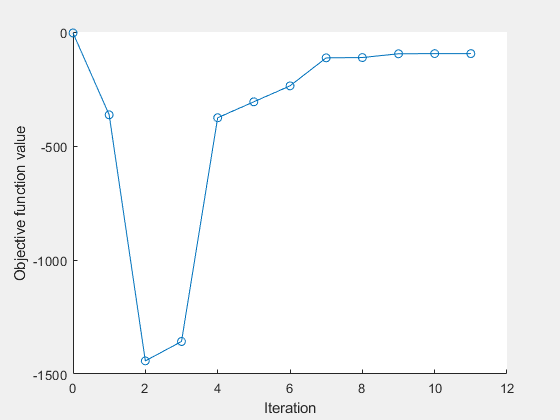


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


%do we want complex-amplitude ('cmplxAmpl') or phase-only ('phase_op3') modulation in the far-field?
modType = 'cmplxAmpl';
if max(abs(bessel_modes(2,:))) && strcmp(modType,'phase_op3'); error('Phase-only modulation is not supported for non-zero OAM values. Set L_max = 0 if you want phase-only modulation.'); end

%objective function and constraints
optimCase = 'obj:Kx_st:Kz=Kx*R,Fz=0,Kx<=0';
% optimCase = 'obj:Kx_st:Ky=Kx,Kxy=Kx,Kxny=Kx,Kz=Kx*R,Fx=0,Fy=0,Fz=0,Kx<=0';

%optimiser starting field; can either be '0oamModes' (Gaussian-like profile) or 'random'
Start = '0oamModes';

%desired ratio between z and x stiffness
zxRatio = NA/4;

%-----run the optimiser-----
OptmSol = Optimiser_FUN(modType,optimCase,Start,OptmSetup,b2v,zxRatio);



%far-field amplitudes of the optimised field (in the Bessel basis)
E_optim = OptmSol.SolutionInFarField;
%BSCs of the optimised field (this is the incident beam)
beam_optim = OptmSol.SolutionInBSCs;


## Enhancement

%Gaussian-like beam for reference
[beam_Gauss, E_gauss] = referenceGaussian(N_modes,bessel_modes,b2v,wavelength_medium);
%directions along which to evaluate enahncement (in Cartesian coords)
dirs = [[1; 0; 0],[0; 1; 0],[0; 0; 1]];

%stiffness enhancements
[~,k_enh] = calcEnhancement(beam_optim,beam_Gauss,dirs,dx,radius,T,0,1);

%volume reduction    
V_red = prod(sqrt(k_enh));

disp(sprintf(['stiffness enhancements in x, y, z are \n' num2str(k_enh,3) '\n\n'...
              'volume reduction is \n' num2str(V_red,3)]))

stiffness enhancements in x, y, z are 
22.5      22.5      19.3

volume reduction is 
98.8


## Force curves

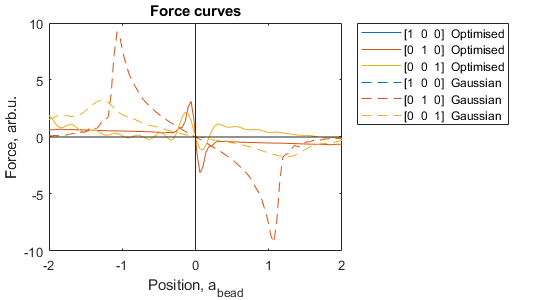

%-----force curves-----
range = 2*radius;
N_points = 100;
dirsF = [[1; 0; 0],[0; 1; 0],[0; 0; 1]];
eq = [[0; 0; 0],[0; 0; 0]];
beams = [beam_optim beam_Gauss];
[fCurves,pos] = forceCurves(dirsF,range,N_points,beams,eq,T);
posPlot = pos/radius; xlbl = 'Position, a_{bead}';
forceCurves_plot(fCurves,posPlot,dirsF,xlbl,'Force curves');

## Fields

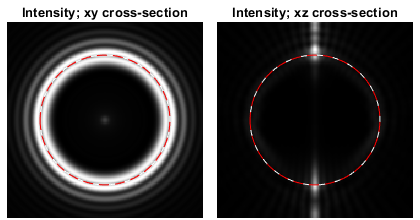

%-----particle plane-----
res = 160;           %resolution at which to plot the fields
plotIntCrossSections(beam_optim,T_sc,T_int,r_plot,res,radius);

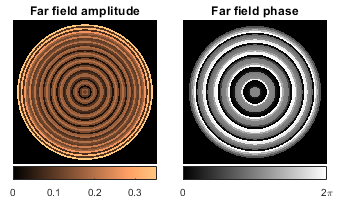



%-----far-field------
plotFarfield_UB(E_optim,bessel_modes);